# EE 366/CE 366/CS 380 Mid-term Exam 2023 Solution

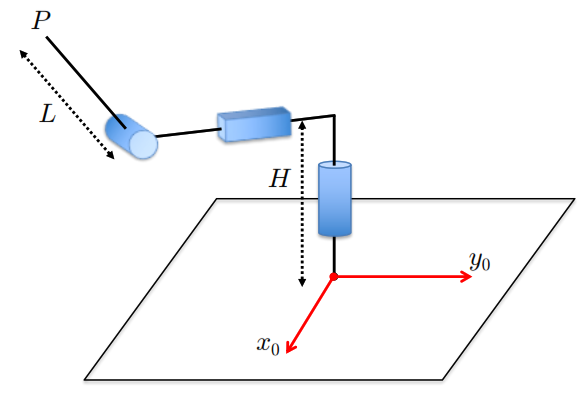

## Question (a) DH Frame Assignment and Parameters

*Complete the assignment of Denavit-Hartenberg (DH) frames and fill in the associated table of parameters. Assign the last frame by carefully considering the remaining parts of this question. Moreover, the frame assignment should be such that all constant DH parameters are non-negative and the value of the joint variables qi, are strictly positive in the shown configuration.* 

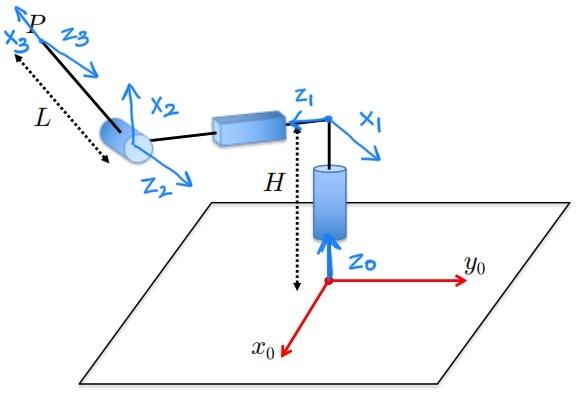


$$\matrix{
\text{Link} & \theta & d & a & \alpha \cr
1 & \theta_1 & H & 0 & 90^\circ \cr
2 & 90^\circ & d_2 & 0 & 90^\circ \cr
3 & \theta_3 & 0 & L & 0
}$$


## Question (b) Forward Kinematics

*Find the coordinates of the point P in the (x0,y0,z0) frame. *

We can obtain coordinates using forward kinematics. 

syms t
syms theta_1(t) d_2(t) theta_3(t)
syms H L
T01 = createA(theta_1,H,0,deg2rad(90))

$$T01(t) = \left(\begin{array}{cccc} \cos\left(\theta_{1}\left(t\right)\right) & 0 & \sin\left(\theta_{1}\left(t\right)\right) & 0\\ \sin\left(\theta_{1}\left(t\right)\right) & 0 & -\cos\left(\theta_{1}\left(t\right)\right) & 0\\ 0 & 1 & 0 & H\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12 = createA(deg2rad(90),d_2,0,deg2rad(90))

$$T12(t) = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 1 & 0 & 0 & 0\\ 0 & 1 & 0 & d_{2}\left(t\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T23 = createA(theta_3,0,L,0)

$$T23(t) = \left(\begin{array}{cccc} \cos\left(\theta_{3}\left(t\right)\right) & -\sin\left(\theta_{3}\left(t\right)\right) & 0 & L\,\cos\left(\theta_{3}\left(t\right)\right)\\ \sin\left(\theta_{3}\left(t\right)\right) & \cos\left(\theta_{3}\left(t\right)\right) & 0 & L\,\sin\left(\theta_{3}\left(t\right)\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T03 = T01*T12*T23

$$T03(t) = \left(\begin{array}{cccc} \sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{3}\left(t\right)\right) & \cos\left(\theta_{3}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & \sin\left(\theta_{1}\left(t\right)\right)\,d_{2}\left(t\right)+L\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{3}\left(t\right)\right)\\ -\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{3}\left(t\right)\right) & -\cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(\theta_{3}\left(t\right)\right) & \sin\left(\theta_{1}\left(t\right)\right) & -\cos\left(\theta_{1}\left(t\right)\right)\,d_{2}\left(t\right)-L\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{3}\left(t\right)\right)\\ \cos\left(\theta_{3}\left(t\right)\right) & -\sin\left(\theta_{3}\left(t\right)\right) & 0 & H+L\,\cos\left(\theta_{3}\left(t\right)\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

So, coordinates of P are

T = T03(t);
P = T(1:3,4)

$$P = \left(\begin{array}{c} \sin\left(\theta_{1}\left(t\right)\right)\,d_{2}\left(t\right)+L\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{3}\left(t\right)\right)\\ -\cos\left(\theta_{1}\left(t\right)\right)\,d_{2}\left(t\right)-L\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{3}\left(t\right)\right)\\ H+L\,\cos\left(\theta_{3}\left(t\right)\right) \end{array}\right)$$

## Question (c) Inverse Kinematics

If H = 2, L = 2, can this manipulator reach the coordinates P = (2.6,-1.5,3)? If yes, find all possible configurations in which you can achieve this point. 

### Geometric Approach

Given $P=(x,y,z)$, let us first find $\theta_3$ geometrically, by projecting onto the $x_2-y_2$ plane,


$$L\cos\theta_3 = z-H \\
\Rightarrow \cos\theta_3 = \frac{z-H}{L} \\
\theta_3 = \arctan2\left(\pm\sqrt{1-\cos^2\theta_3},\cos\theta_3\right) = \arctan2\left(\pm\sqrt{\frac{L^2-(z-H)^2}{L^2}},\frac{z-H}{L}\right) $$


If the desired point is in the upper half above the horizontal length of the manipulator, then $z>H$and $\frac{z-H}{L}>0$. Consequently, 

Note that $\theta_3\in (-180^\circ,180^\circ]$. There is going to be a positive solution, $\theta_3^+$, and a negative solution, $\theta_3^-$.

From the same projection, we can find $d_2$:


$$d_2+L\sin\theta_3=\sqrt{x^2+y^2} \\
\Rightarrow d_2 = \sqrt{x^2+y^2} -L\sin\theta_3$$


Note that for $\theta_3^+$, there is a possibility that we could get a negative $d_2$, when $\sqrt{x^2+y^2}<L\sin\theta_3$. This will be the case for points close to the center of the manipulator. We'll address this case after finding $\theta_1$.

By projecting onto the $x_0-y_0$ plane,


$$\theta_1 = 90^\circ+\alpha \\
\alpha = \arctan2(y,x) 
$$


For the special case, $\{\theta_3^+,d_2<0\}$, we can rotate the first joint to move the manipulator to the opposite side, i.e.

$\alpha' = \alpha+180^\circ \\
\Rightarrow \theta_1^{'} = 90^\circ+\alpha' = 270^\circ+\alpha = -(90^\circ-\alpha)$.

Correspondingly,


$$d_2' = -\sqrt{x^2+y^2} -L\sin\theta_3^{-}$$


So, the two solutions, given $\left(x,y,z\right)$, are:


$$\matrix{
\text{Solution number} &\quad & \text{Conditions} & \qquad & \theta_3 & \quad & d_2 & \quad & \theta_1 \cr
1 &\quad & \text{None} & \qquad & \theta_3^- & \quad & \sqrt{x^2+y^2}-L\sin\theta_3^- & \quad & 90^\circ+\alpha \cr
2 &\quad & \sqrt{x^2+y^2}\geq L\sin\theta_3^+ & \qquad & \theta_3^+ & \quad & \sqrt{x^2+y^2}-L\sin\theta_3^+ & \quad & 90^\circ+\alpha \cr
2 &\quad & \sqrt{x^2+y^2}< L\sin\theta_3^+ & \qquad & \theta_3^- & \quad & -\sqrt{x^2+y^2}-L\sin\theta_3^- & \quad & 270^\circ+\alpha \cr

}$$


For the given P,

z = 3;
x = 2.6;
y = -1.5;
h = 2;
l = 2;
c3 = (z-h)/l;
theta3_1 = atan2d(sqrt(1-c3^2),c3)

theta3_1 = 60.0000

theta3_2 = atan2d(-sqrt(1-c3^2),c3)

theta3_2 = -60.0000

d2_1 = sqrt(x^2+y^2)-l*sind(theta3_1)

d2_1 = 1.2696

d2_2 = sqrt(x^2+y^2)-l*sind(theta3_2)

d2_2 = 4.7337

theta1 = atan2d(y,x)+90

theta1 = 60.0184

### **Analytical Approach**

IK for this problem may be easier with the analytical approach. We have the following equations:


$$d_2\sin\theta_1+L\sin\theta_1\sin\theta_3 = x \quad (1)\\
-d_2\cos\theta_1-L\cos\theta_1\sin\theta_3 = y \quad (2)\\
H+L\cos\theta_3 = z \quad (3)$$


**Finding **$\theta_3$

From (3), we can easily find out $\theta_3$:


$$\cos\theta_3 = \frac{z-H}{L} \\
\theta_3 = \arctan2\left(\pm\sqrt{1-\cos^2\theta_3},\cos\theta_3\right) = \arctan2\left(\pm\sqrt{\frac{L^2-(z-H)^2}{L^2}},\frac{z-H}{L}\right) $$


**Finding **$d_2$

Now, let's square (1) and (2), and then add them:


$$x^2+y^2 = d_2^2\,\sin^2\theta_1 + d_2^2\,\cos^2\theta_1 + L^2\sin^2\theta_3\,\sin^2\theta_1 + L^2\sin^2\theta_3\,\cos^2\theta_1 + 2d_2L\sin\theta_3\,\sin^2\theta_1 + 2d_2L\sin\theta_3\,\cos^2\theta_1 \\
x^2+y^2 = d_2^2+L^2\,\sin^2\theta_3+2d_2L\sin\theta_3 \\
0 = d_2^2+(2L\sin\theta_3)\,d_2 + (L^2\,\sin^2\theta_3-x^2-y^2)$$


This is a quadratic in $d_2$, so


$$d_2= \frac{-2L\sin\theta_3\pm\sqrt{4L^2\,\sin^2\theta_3-4(L^2\,\sin^2\theta_3-x^2-y^2)}}{2} \\
d_2= -L\sin\theta_3 \pm \sqrt{x^2+y^2} $$


For $\theta_3^+$, the two possible solutions for $d_2$, are:


$$d_2^1 = -L\sin\theta_3^+ + \sqrt{x^2+y^2} \\
d_2^2 = -L\sin\theta_3^+ - \sqrt{x^2+y^2}$$


But, note that $\sin\theta_3^+>0$, which means that $d_2^2<0$, and so invalid. Furthermore, $d_2^1$ is valid only when $\sqrt{x^2+y^2}\geq L\sin\theta_3^+$.

For $\theta_3^-$, we have that $\sin\theta_3^-<0$ and $\sin\theta_3^-=-\sin\theta_3^+$, and the two solutions are:


$$d_2^3 = -L\sin\theta_3^- + \sqrt{x^2+y^2} \\
d_2^4 = -L\sin\theta_3^- - \sqrt{x^2+y^2} $$


From these, $d_2^4$ is only valid when $\sqrt{x^2+y^2} < L\sin\theta_3^+$. Note that this is the condition when no valid solution is obtained from $\theta_3^+$. So, the solutions up till this point are:


$$\left\{\matrix{
\left(\cdot,\,\sqrt{x^2+y^2}-L\sin\theta_3^+,\,\theta_3^+\right) \text{ and } \left(\cdot,\,\sqrt{x^2+y^2}-L\sin\theta_3^-,\,\theta_3^-\right) & \qquad\text{if }\sqrt{x^2+y^2}\geq L\sin\theta_3^+\cr
\left(\cdot,\,-\sqrt{x^2+y^2}-L\sin\theta_3^-,\,\theta_3^-\right) \text{ and } \left(\cdot,\,\sqrt{x^2+y^2}-L\sin\theta_3^-,\,\theta_3^-\right) & \qquad\text{if }\sqrt{x^2+y^2}< L\sin\theta_3^+
}\right.$$


**Finding **$\theta_1$

Finally for $\theta_1$, (1) and (2) are:


$$(d_2+L\sin\theta_3)\sin\theta_1 = x\\
-(d_2+L\sin\theta_3)\cos\theta_1 = y
$$


Thus,


$$\theta_1=\left\{\matrix{
\arctan2(x,-y) &\qquad\text{if }d_2+L\sin\theta_3>0 \cr
\arctan2(-x,y) &\qquad\text{if }d_2+L\sin\theta_3<0
}\right.$$


and solutions are:


$$\left\{\matrix{
\left(\arctan2(x,-y),\,\sqrt{x^2+y^2}-L\sin\theta_3^+,\,\theta_3^+\right) \text{ and } \left(\arctan2(x,-y),\,\sqrt{x^2+y^2}-L\sin\theta_3^-,\,\theta_3^-\right) & \qquad\text{if }\sqrt{x^2+y^2}\geq L\sin\theta_3^+\cr
\left(\arctan2(-x,y),\,-\sqrt{x^2+y^2}-L\sin\theta_3^-,\,\theta_3^-\right) \text{ and } \left(\arctan2(x,-y),\,\sqrt{x^2+y^2}-L\sin\theta_3^-,\,\theta_3^-\right) & \qquad\text{if }\sqrt{x^2+y^2}< L\sin\theta_3^+
}\right.$$


## Question (d) Jacobian

**We wish to move the point P at a velocity (0.5,0.5,-0.5) m/s. At what rate will we have to move the joints?**

We can find $J_v$ by differentiating $P(t):$

collect(diff(P,t),diff(theta_1,t));
J = [L*cos(theta_1)*sin(theta_3)+d_2*cos(theta_1) sin(theta_1) L*cos(theta_3)*sin(theta_1);
    L*sin(theta_1)*sin(theta_3)+d_2*sin(theta_1) -cos(theta_1) -L*cos(theta_3)*cos(theta_1);
    0 0 -L*sin(theta_3)]

$$J(t) = \left(\begin{array}{ccc} \cos\left(\theta_{1}\left(t\right)\right)\,d_{2}\left(t\right)+L\,\cos\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{3}\left(t\right)\right) & \sin\left(\theta_{1}\left(t\right)\right) & L\,\cos\left(\theta_{3}\left(t\right)\right)\,\sin\left(\theta_{1}\left(t\right)\right)\\ \sin\left(\theta_{1}\left(t\right)\right)\,d_{2}\left(t\right)+L\,\sin\left(\theta_{1}\left(t\right)\right)\,\sin\left(\theta_{3}\left(t\right)\right) & -\cos\left(\theta_{1}\left(t\right)\right) & -L\,\cos\left(\theta_{1}\left(t\right)\right)\,\cos\left(\theta_{3}\left(t\right)\right)\\ 0 & 0 & -L\,\sin\left(\theta_{3}\left(t\right)\right) \end{array}\right)$$

To answer this question we can find the joint velocities at the current configuration, given the end-effector velocities by the expression $\dot{q} = J^{-1}(\theta_1,d_2,\theta_3)\,v$. Substituting the values of the parameters and $(\theta_1,d_2,\theta_3)$ obtained from part (c),

Jn = subs(J,{theta_1 d_2 theta_3 L},{pi/3 1.3 pi/3 2})

$$Jn(t) = \left(\begin{array}{ccc} \frac{\sqrt{3}}{2}+\frac{13}{20} & \frac{\sqrt{3}}{2} & \frac{\sqrt{3}}{2}\\ \frac{13\,\sqrt{3}}{20}+\frac{3}{2} & -\frac{1}{2} & -\frac{1}{2}\\ 0 & 0 & -\sqrt{3} \end{array}\right)$$

Now, let's invert this matrix and multiply it with the provided velocity vector $[0.5,0.5,-0.5]^T$:

double(inv(Jn))*[.5;.5;-.5]

ans =     0.2253
   -0.1057
    0.2887


As we can see, the joint rates of the first and third revolute joints are less than 0.3, and so the specified velocity is achievable. 

## Question (e) Angular Velocity 

**If the point P is moving at the velocity specified in the previous part, does it have a non-zero angular velocity? If yes, find the velocity, and if no, provide justification.**

Yes, it has an angular velocity, which will be the same as the angular velocity of the last link. Since it is a chain of rigid bodies, we can find the angular velocity of last link by taking the vector sum of frame-frame angular velocities, i.e. 


$$\omega_{03}^0 = \omega_{01}^0 + \omega_{12}^0 +\omega_{23}^0 \\
\omega_{03}^0 = \dot{\theta}_1\,z_0^0 + 0 + \dot{\theta}_3\,z_2^0 $$


Let's now find the entries in this expression. We know that $z_0^0 = \left[\matrix{0 & 0 & 1}\right]^T$. We can find $z_2^0$ by finding third column of $T_{02}$:

T02 = T01*T12

$$T02(t) = \left(\begin{array}{cccc} 0 & \sin\left(\theta_{1}\left(t\right)\right) & \cos\left(\theta_{1}\left(t\right)\right) & \sin\left(\theta_{1}\left(t\right)\right)\,d_{2}\left(t\right)\\ 0 & -\cos\left(\theta_{1}\left(t\right)\right) & \sin\left(\theta_{1}\left(t\right)\right) & -\cos\left(\theta_{1}\left(t\right)\right)\,d_{2}\left(t\right)\\ 1 & 0 & 0 & H\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Thus,


$$\omega_{03}^0 = \dot{\theta}_1\,\left[\matrix{0\cr 0\cr 1}\right] + \dot{\theta}_3\,\left[\matrix{\cos\theta_1\cr \sin\theta_1\cr 0}\right]$$


Substituting $\theta_1=60^\circ$ from (c) and $\left(\dot{\theta}_1,\dot{\theta}_3\right) = (0.22,0.29)$ from (d), we have:

w_03 = 0.22*[0;0;1]+0.29*[cosd(60);sind(60);0]

w_03 =     0.1450
    0.2511
    0.2200


## Question (f) Singularities

**Find the singular configurations (if any) for this manipulator and argue about the velocity directions that cannot be instantaneously achieved in those configurations.**

We can find singular configurations by finding determinant of Jacobian and equating it to zero. The determinant is:

simplify(det(J))

$$ans(t) = L^{2}\,{\sin\left(\theta_{3}\left(t\right)\right)}^{2}+d_{2}\left(t\right)\,L\,\sin\left(\theta_{3}\left(t\right)\right)$$

Since $L\neq 0$, this determinant will be zero under one of two conditions:

- $\theta_3=0$ or $\theta_3=180^\circ$: At this configuration, it is not possible to instantaneously move vertically in the $z_0$ direction.

- $d_2=-L\sin\theta_3$: This translates to the point P being on the $z_0$ axis. At this singularity, the manipulator cannot move instantaneously orthogonal to the prismatic joint or in the $x_1$direction. This can also be seen by rewriting the Jacobian in the coordinates of frame 1, as shown below. In this case we can see that velocity in the $\dot{x}_1$ direction is zero irrespective of the joint velocities if $d_2+L\sin\theta_3=0$.

R01 = T01(t);
R01 = R01(1:3,1:3);
R10 = R01.';
simplify(R10 * J)

$$ans(t) = \left(\begin{array}{ccc} d_{2}\left(t\right)+L\,\sin\left(\theta_{3}\left(t\right)\right) & 0 & 0\\ 0 & 0 & -L\,\sin\left(\theta_{3}\left(t\right)\right)\\ 0 & 1 & L\,\cos\left(\theta_{3}\left(t\right)\right) \end{array}\right)$$